# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder, any output images you might have saved and this livescript file (with the required images plotted).

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./sift');
addpath('./data');
% Also add the directory for SIFT to path as it will be used later.

# Lab 3 :Image Registration

An affine transformation is written as:


$$\left(\begin{array}{l}
\tilde{x} \\
\tilde{y}
\end{array}\right)=\left(\begin{array}{ll}
a & b \\
c & d
\end{array}\right)\left(\begin{array}{l}
x \\
y
\end{array}\right)+\left(\begin{array}{l}
t_{x} \\
t_{y}
\end{array}\right)=A\left(\begin{array}{l}
x \\
y
\end{array}\right)+t$$


Apart from rotation, translation and scaling, it also allows strecthing the image in an arbitrary dimension. 

#### Ex 3.1

What is the minimal number of point correspondences, K, required in order to estimate an affine transformation between two images ?		

#### Your answer here (with explanation).	

"In an affine transformation there are six unknowns. Each point has a x and y coordinate. Therefore we need three point correspondances."

ans = "In an affine transformation there are six unknowns. Each point has a x and y coordinate. Therefore we need three point correspondances."

Once you have found a proper coordinate transformation between two images, you can use the provided function `affine_warp` to warp the source image and create a warped image. Let’s try it. 	 

#### Ex 3.2

Load the image `mona.png` to the variable `img`. Try running the following code snippet :

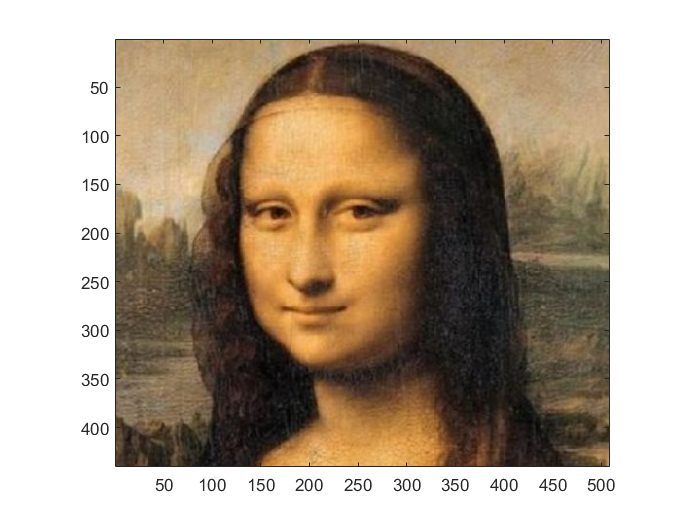

img = imread('data/mona.png'); 
imagesc(img); axis image;

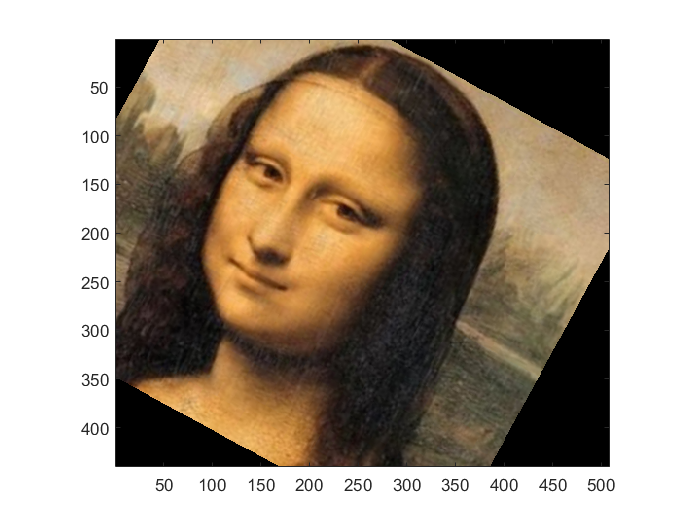


A = [0.88 -0.48; 0.48 0.88];
t = [100;-100];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;	

Change the values in `A` and `t` to see what happens. Swap A for a `eye(2,2)` to try a pure translation. 

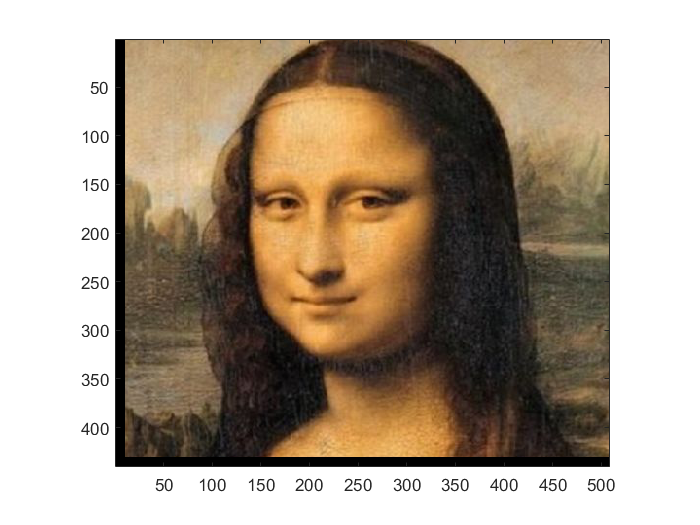

A = eye(2,2);
t = [10;-10];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;	

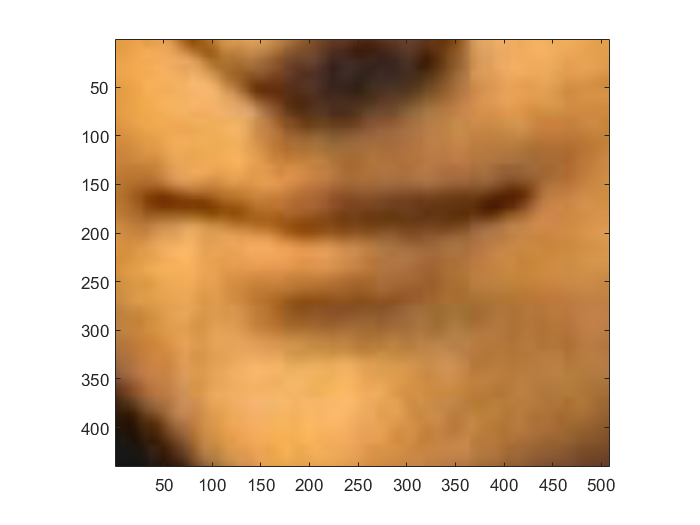


A = eye(2,2)*6;
t = [-1000;-1500];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;	

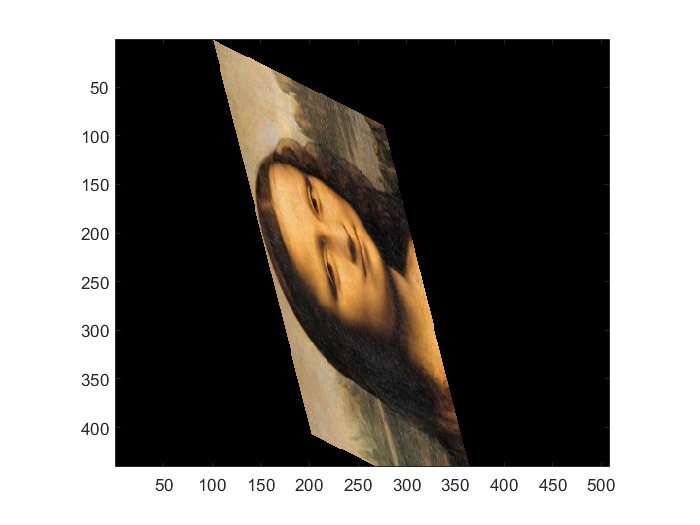


A = [0.1 0.2;0.4  0.1]*2;
t = [100;0];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;	

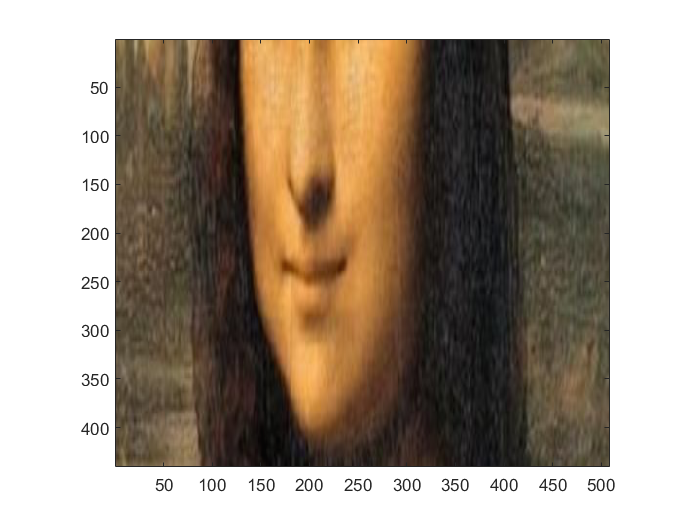


A = [1 0;0  3];
t = [0; -600];
target_size = size(img);
warped = affine_warp(target_size, img, A, t); imagesc(warped);
axis image;

#### Explain your observations.

"If A is not a diagonal matrix a rotation is applied. If the norm of A is larger than one the image is resized larger and if the norm is smaller than one the image resolution is lowered. t applies a translation in x and y."

ans = "If A is not a diagonal matrix a rotation is applied. If the norm of A is larger than one the image is resized larger and if the norm is smaller than one the image resolution is lowered. t applies a translation in x and y."

#### Ex 3.3					

For any estimation task it is a good idea to have at least one test case where you know what the answer should be. In this exercise you should make such a test case for RANSAC. Start by generating random points, `pts`, and a random transformation. Then transform these points to create a `pts_tilde`. You now have two sets of points related by a known affine transformation as in (3.1). In the following exercises you will try to estimate this transformation. As you know the correct answer it is easy to detect if you make a mistake. 					

**Make a function** 

that generates a test case for estimating an affine transformation. The transformation should map `pts` to `pts_tilde.` Don't add any outliers now. Outputs `pts` and `pts_tilde` should be `2 X N-arrays`. Also output the *true* transformation, so you know what to expect from your code.

After you have written the function, test it with a few runs here :

[pts, pts_tilde, A_true, t_true] = affine_test_case;

A_true

A =    43.0000   29.0000
   41.0000   10.0000


A_true =     43    29
    41    10


t =    12.0000
   45.0000


t_true

t_true =     12
    45


#### Ex 3.4 

Make a minimal solver for the case of affine transformation estimation. In other words, **make a function**

that estimates an affine trasnformation mapping `pts` to `pts_tilde`, where `pts` and `pts_tilde` are `2 X K - arrays` and `K` is the number you found in *Ex 3.1*. Try your function on points from the test case in *Ex 3.3*.

[pts, pts_tilde, A_true, t_true] = affine_test_case;
[A, t] = estimate_affine(pts, pts_tilde)

A =    41.0000   20.0000
    4.0000   27.0000


t =     21
    33


A_true

A_true =     41    20
     4    27


t_true

t_true =     21
    33


#### Ex 3.5

Make a function

that computes the lengths of 2D residual vectors. the funciton should return an array with N values. *Hint : *Given a `2 X N` matrix - `M`, the column-wise sum of the squared elements can be computed as `sum(M.^2, 1)`. 

**Ex 3.6** 

Modify your function `affine_test_case `to create a new function `affine_test_case_outlier `that takes a parameter `outlier_rate` and produces a percentage of outliers among the output points. For example, the outliers could be spread randomly over the image. 

**Ex 3.7**

**Make a function**					

that uses RANSAC to find an affine transformation between two sets of points. (Like before the transformation should map `pts` onto `pts_tilde`.) Test your function on test cases generated with your function `affine_test_case_outlier`. Try different outlier rates and `threshold` values. Make sure that you get the right transformation with a reasonable number of outliers. 

outlier_rate = 0.2;
[pts, pts_tilde, A_true, t_true] = affine_test_case_outlier(outlier_rate);
[A,t] = ransac_fit_affine(pts, pts_tilde, 1e-14);

A

A =   273.0000   12.0000
  392.0000  478.0000


A_true

A_true =    273    12
   392   478



t

t =     30
   166


t_true

t_true =     30
   166


Explain your observations with different values of `threshold. `Why do arbitrarily small values of `threshold` work in this case?

"If the threshold is too large some of the outliers will be falsely identified as inliers and thereby the resulting affine transformation will be incorrect. For small thresholds the number of outliers will converge towards their true percentage. Small values of threshold work in this case, because we have a set of points from pts and pts_tilde that relate to each other by the original affine transformation A_true and t_true. On these sets of points the number of outliers will be exactly the outlier_rate."

ans = "If the threshold is too large some of the outliers will be falsely identified as inliers and thereby the resulting affine transformation will be incorrect. For small thresholds the number of outliers will converge towards their true percentage. Small values of threshold work in this case, because we have a set of points from pts and pts_tilde that relate to each other by the original affine transformation A_true and t_true. On these sets of points the number of outliers will be exactly the outlier_rate."

#### Ex 3.8

For this exercise, you should use the function

from *Lab 1* to extract SIFT features. Note that it only works for grayscale images, so if you have a colour image you need to convert it to grayscale before using `extractSIFT`. To match features you can use the built-in function matchFeatures. To use the Lowe criterion (with threshold 0.8) you should use the following options: 

**Write a function**

that uses SIFT and RANSAC to align the source image to the target image. To perform the actual warping, use :

inside the `align_images` function. Be very careful about the order in which you send the points to RANSAC.

Tip : You could suppress warnings in MATLAB with `warning('off').`

#### Ex 3.9

Align `vermeer_source.png` to `vermeer_target.png `using your function` align_images. `Once done, plot the source, target and warped images. 

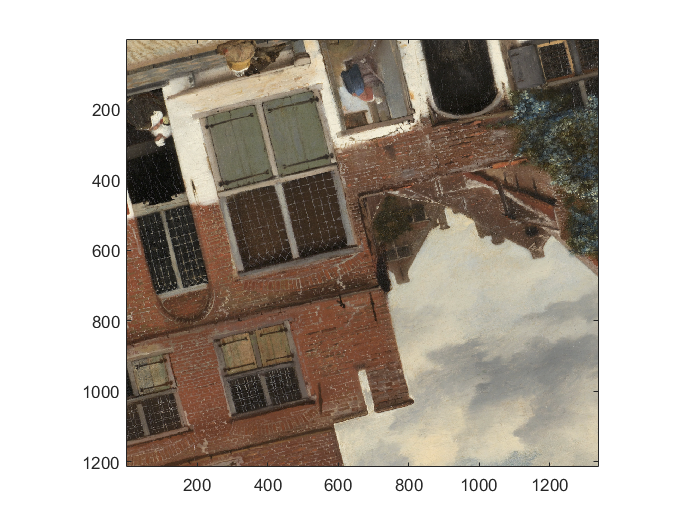

source = imread('data/vermeer_source.png'); 
imagesc(source); axis image;

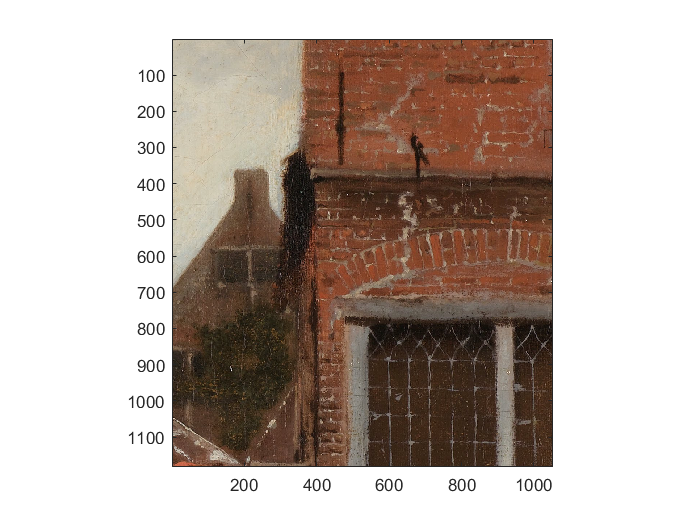

target = imread('data/vermeer_target.png'); 
imagesc(target); axis image;

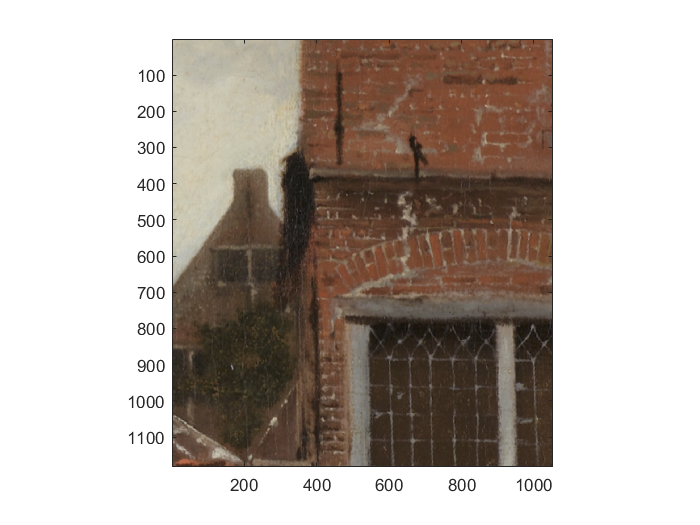


warning('off')
warped = align_images(source, target, 20);
imagesc(warped); axis image;

#### Ex 3.10

Medical images often have less local structure, making SIFT matching more difficult. It often works better if we drop the rotation invariance. The provided `extractSIFT` function has an option for this. 

assumes that the image has a default orientation.

Modify you `align_images` so it takes the outlier threshold, `threshold` as an input and a boolean, `upright` stating whether the images are have the same orientation, i.e. 

Try aligning the images *CT_1.jpg* and *CT_2.jpg*. Try with and without rotation invariance and try different outlier thresholds. Once done, plot the source, target and warped images. 

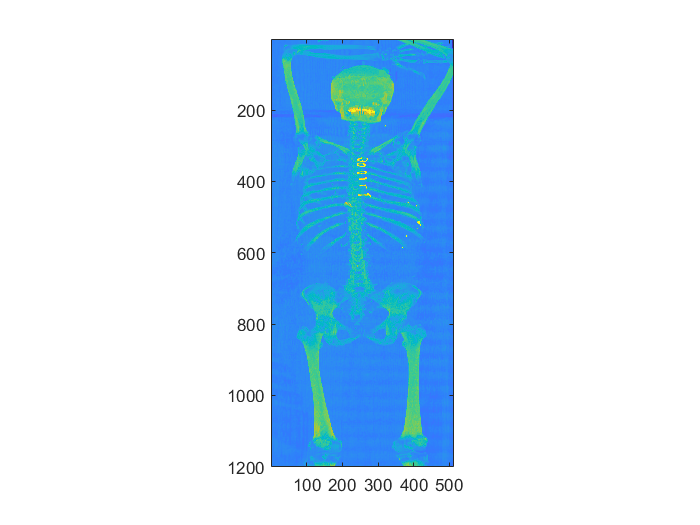

source = imread('data/CT_1.jpg'); 
imagesc(source); axis image;

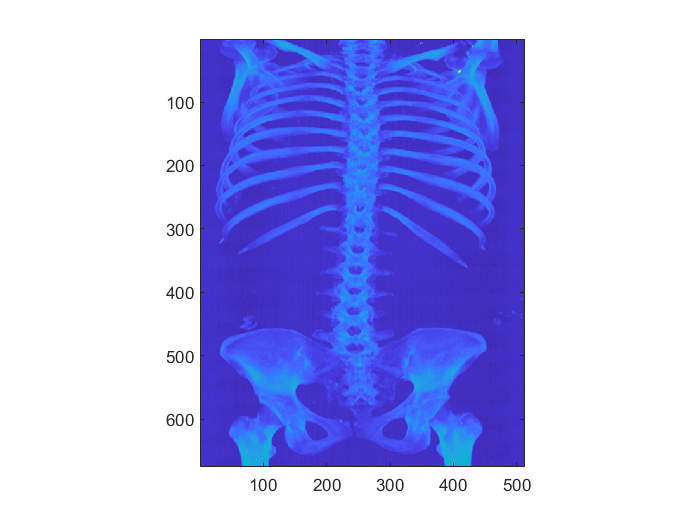

target = imread('data/CT_2.jpg'); 
imagesc(target); axis image;

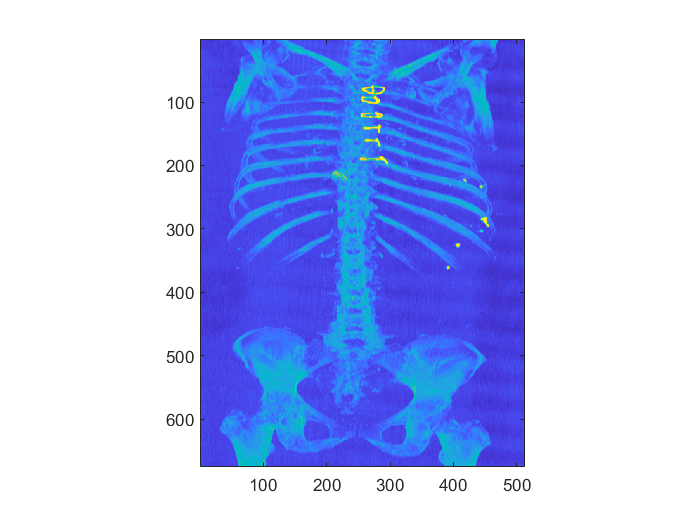


warning('off')
warped = align_images_v2(source, target, 20, true);
imagesc(warped); axis image;

**Explain your observations about usage of **`upright`**.**

""

ans = ""

#### Ex 3.11

Try aligning *tissue_fluorescent.tif *and *tissue_brightfield.tif*. In the fluorescent image, the intensities are basically inverted, so you need to invert one of the images before computing descriptors. (Otherwise you won’t get any good matches.) If you used `read_as_grayscale` to load the images, they should have values between 0 and 1 so you can invert it by taking 

Once done, plot the source, target and warped images. 

%% Your code here


# Warping

#### Ex 3.12

So far you have used Matlabs function for warping. The reason is that it is difficult to write a Matlab function for warping that is not painfully slow. Now you will get to write one anyway, but we will only use it for very small images. 

**Write a function**

that gives you the pixel value at `position`. If the elements of `position` are not integers, select the value at the closest pixel. If it is outside the image, return 1 (=white). Try your function on a simple image to make sure it works. 

%% Your code here


#### Ex 3.13

Now, you will do a warping function that warps a `16 X 16` image according to the coordinate transfomation provided in `transform_coordinates.m`. 

Write a function

that warps source according to the function `transform_coordinates` and forms an output 16 X 16 image `warped`. `transform_coordinates` defines the inverse transformation from target to source, that is, it takes a 2-vector `target_pos` as input, and maps it to the source image. In your function, loop over all target pixels and use the inverse transformation along with your function `sample_image_at` to extract pixel values from the source image. Try the function on `source_16x16.tif` and plot the answer using imagesc. You will know if you get it right. Once done, plot the warped image. 

%% Your code here


# Least Squares

#### Ex 3.14

Write a function

	 that estimates an affine transformation mapping `pts` to `pts_tilde `in least squares sense, i.e., all points in `pts` and `pts_tilde` are used to compute the transformation. (Depending on how you wrote you estimate_affine.m, this might be very easy.) Use it on the inliers from RANSAC to refine the estimate. Add this to `align_images `to form a new function` align_images_inlier_ls` and test it on the `Vermeer` images for different outlier thresholds. 

%% Your code here


**Do you notice an improvement?** Explain your observations.

""

ans = ""